% 目的：找到FRF求解方法
% 文献：Flexural wave propagation in beams with periodically attached vibration absorbers: Band-gap behavior and band formation mechanisms
% 
% 状态：失败，不是动刚度格式问题
% 备注：尝试更换动刚度矩阵格式。
% ================================================

## 参数设置

clear;clc


%% 1. 几何参数 (Table 1)
geometry.h = 0.015;      % 梁高度 [m]
geometry.l = 0.01;       % 间距 [m]
geometry.r1 = 0.013;     % 内半径 [m]
geometry.r2 = 0.015;     % 中间半径 [m]
geometry.r3 = 0.018;     % 外半径 [m]
geometry.L = 0.1;        % 梁总长度 [m]
geometry.N = 6;         % 单元个数

%% 2. 材料参数 (Table 2)
% 铝层参数
material.aluminum.E = 7e10;          % 杨氏模量 [Pa]
material.aluminum.G = 2.7e10;        % 剪切模量 [Pa]
material.aluminum.rho = 2700;        % 密度 [kg/m^3]

% 橡胶层参数
material.rubber.E = 7.748e5;         % 杨氏模量 [Pa]
material.rubber.G = 2.6e5;           % 剪切模量 [Pa]
material.rubber.rho = 1300;          % 密度 [kg/m^3]

% 铜层参数
material.copper.E = 1.65e11;         % 杨氏模量 [Pa]
material.copper.G = 7.53e10;         % 剪切模量 [Pa]
material.copper.rho = 8700;          % 密度 [kg/m^3]

%% 3. 截面特性计算
% 梁的横截面积
geometry.A = pi*(geometry.r3^2-geometry.r2^2);
% 梁的惯性矩
geometry.I = pi*(geometry.r3^4-geometry.r2^4)/4;

%% 4. DVA参数计算
% 形状参数 S = l / [(r1 + r2) * ln(r2/r1)]
geometry.DVA.S = geometry.l / ((geometry.r1 + geometry.r2) * log(geometry.r2/geometry.r1));

% DVA质量 m = ρ_Cu * π * （r3²-r2²） * h
material.DVA.m = material.copper.rho * pi * (geometry.r1^2) * geometry.h;

% DVA弹簧刚度 k = [π(5 + 3.29S²)Gl] / ln(r₂/r₁)
material.DVA.k = (pi * (5 + 3.29*geometry.DVA.S^2) * material.rubber.G * geometry.l) / ...
             log(geometry.r2/geometry.r1);







## 计算和结果

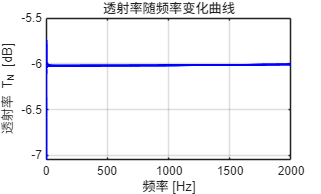


%% 频率扫描范围
omega_values = linspace(10, 14000, 10000);
fre_values = omega_values ./ (2*pi());  % 转换为Hz
T_N_results = zeros(size(omega_values)); % 存储透射率结果

% 检查波束随频率变化，后续画图观察
k_record = zeros(size(omega_values));

%% 主循环
for i = 1:length(omega_values)
    omega = omega_values(i);
    
    % 计算当前频率下的透射率
    [T_N, k] = calculate_transmission_rate(omega, material, geometry);
    % 转换为分贝(dB)：T_N(dB) = 20*log10(|T_N|)
    % T_N_results(i) = T_N;
    T_N_results(i) = 20 * log10(abs(T_N));
    
    k_record(i) = k;
end

%% 绘制结果
figure;
plot(fre_values, T_N_results, 'b-', 'LineWidth', 2);
xlabel('频率 [Hz]');
ylabel('透射率 T_N [dB]');
title('透射率随频率变化曲线');
grid on;
xlim([0 2000]);

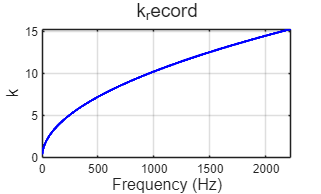



plot_k(fre_values, k_record)

function [T_N, k_record] = calculate_transmission_rate(omega, material, geometry)
    % 构建全局矩阵系统
    % 输入参数：
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %   omega : 角频率 [rad/s]
    %
    % 输出参数：
    %   T_N : 透射率




    % 计算DVA动态刚度
    D0 = calculate_DVA_stiffness(omega, material);

    % 单元长度
    geometry.ucL = geometry.L / geometry.N;
    % La和Lb段单元长度
    La = geometry.ucL/2;  % 假设La和Lb各占一半长度
    Lb = geometry.ucL/2;

    % 计算单元矩阵（La和Lb段）
    [D_La,k_record] = spectral_element_matrix(omega, material, geometry, La);
    D_Lb = spectral_element_matrix(omega, material, geometry, Lb);
    
    % 提取子矩阵块
    D_LL = D_La(1:2,1:2);       % D11(La)
    D_LI = D_La(1:2,3:4);       % D12(La)
    D_IL = D_La(3:4,1:2);       % D21(La)
    D_II_La = D_La(3:4,3:4);    % D22(La)
    
    D_II_Lb = D_Lb(1:2,1:2);    % D11(Lb)
    D_IR = D_Lb(1:2,3:4);       % D12(Lb)
    D_RI = D_Lb(3:4,1:2);       % D21(Lb)
    D_RR = D_Lb(3:4,3:4);       % D22(Lb)

    % 凝聚矩阵
    % 计算公共逆矩阵项
    D_II = D_II_La + D_II_Lb + [D0 0; 0 0];
    inv_D_II = inv(D_II);

    D_LL_ = D_LL - D_LI * inv_D_II * D_IL;
    D_LR_ = -D_LI * inv_D_II * D_IR;
    D_RL_ = -D_RI * inv_D_II * D_IL;
    D_RR_ = D_RR - D_RI * inv_D_II * D_IR;

    % 初始化全局矩阵 (n_elements+1节点，每个节点有2个自由度)
    global_dof = 2 * (geometry.N + 1);
    D_global = zeros(global_dof, global_dof);

    % 激励和响应位置设置
    excitation_dof = 1;  % 激励节点
    response_dof = global_dof - 1;    % 响应节点
    
    % 组装每个单元的矩阵
    for elem = 1:geometry.N

        % 获取单元矩阵
        D_local = [D_LL, D_LI;...
            D_IL, D_II_La];
        
        % 计算全局自由度索引
        start_dof = 2*(elem-1)+1;
        end_dof = start_dof + 3;
        
        % 组装到全局矩阵
        D_global(start_dof:end_dof, start_dof:end_dof) = ...
        D_global(start_dof:end_dof, start_dof:end_dof) + D_local;
    end


    % 已知条件：左端点位移 = 1
    known_disp_dof = excitation_dof; % 位移已知的自由度
    unknown_dofs = setdiff(1:global_dof, known_disp_dof); % 其他自由度
    
    % 分区处理系统方程
    D_kk = D_global(known_disp_dof, known_disp_dof);
    D_ku = D_global(known_disp_dof, unknown_dofs);
    D_uk = D_global(unknown_dofs, known_disp_dof);
    D_uu = D_global(unknown_dofs, unknown_dofs);


    % 已知位移条件
    U_k = 1; % 左端点单位位移激励

    % 求解未知位移
    % K_uu * U_u = -K_uk * U_k
    U_u = D_uu \ (-D_uk * U_k);
    
    % 组装完整的位移向量
    U_full = zeros(global_dof, 1);
    U_full(known_disp_dof) = U_k;
    U_full(unknown_dofs) = U_u;

    % 提取输入和输出位移
    U_in = U_full(excitation_dof);
    U_out = U_full(response_dof);

    T_N = abs(U_out/U_in);


    % 
    % % 计算透射率 T_N = |B11 + B12 * A21 * A11^{-1}|
    % % T_N = abs(B11 + B12 * A21 / A11);
    % T_N = abs(alpha_N(3,1)/ alpha_N(1,1));

end

% 梁谱元矩阵La、Lb %
function [D_beam,kb] = spectral_element_matrix(omega, material, geometry, L)
    % 输入参数：
    %   omega : 角频率 [rad/s]
    %   material : 材料参数结构体
    %   geometry : 几何参数结构体
    %
    % 输出参数：
    %   D_beam : 4×4梁刚度矩阵
    
    % kb计算函数
    kb = (material.aluminum.rho * geometry.A * omega^2 / ...
         (material.aluminum.E * geometry.I))^(1/4);

    [s11, s12, s13, s14, s22, s23, s24] = calculate_matrix_elements(kb, L);

    % 计算分母Δ
    delta = cos(kb*L) .* cosh(kb*L) - 1;
    % 弯曲刚度
    EI = material.aluminum.E * geometry.I;  

    % 构建对称矩阵
    D_beam = EI ./ delta .* [ ...
        s11,  s12,  s13,  s14; ...
        s12,  s22,  s23,  s24; ...
        s13,  s23,  s11, -s12; ...  % s33 = s11, s34 = -s12
        s14,  s24, -s12,  s22  ...  % s44 = s22
    ];

end

function [s11, s12, s13, s14, s22, s23, s24] = calculate_matrix_elements(kb, L)
    s11 = -kb.^3 .* (cos(kb*L).*sinh(kb*L) + sin(kb*L).*cosh(kb*L));
    s12 = -kb.^2 .* sin(kb*L) .* sinh(kb*L);
    s13 = kb.^3 .* (sin(kb*L) + sinh(kb*L));
    s14 = kb.^2 .* (cos(kb*L) - cosh(kb*L));
    s22 = kb .* (cos(kb*L).*sinh(kb*L) - sin(kb*L).*cosh(kb*L));
    s23 = kb.^2 .* (cosh(kb*L) - cos(kb*L));
    s24 = kb .* (sin(kb*L) - sinh(kb*L));
end

function D_0 = calculate_DVA_stiffness(omega, material)
    % 输入参数：
    %   omega : 频率
    %   geometry : 包含材料参数的结构体
    %
    % 输出参数：
    %   D_0 : DVA动刚度

    % 读取参数
    k = material.DVA.k;
    m = material.DVA.m;

    % 计算：
    D_0 = k - k^2 / (k - omega^2 * m);
end


function plot_k(fre, k_record)
    figure;
    plot(fre, k_record, 'b-', 'LineWidth', 2);

    xlabel('Frequency (Hz)', 'FontSize', 12);
    ylabel('k', 'FontSize', 12);
    title(sprintf('k_record'), ...
        'FontSize', 14);
    grid on;
    xlim([0 max(fre)]);
end